addpath '/Users/benoitmuller/Documents/GitHub/opti-manifolds-rotations-estimation/data generation'
clear
rng(05011998)

## Question 10,11,12

fprintf("\n––– Question 10,11,12 –––\n")


––– Question 10,11,12 –––


d = 3;
m = 10;
ma = 1;
kappa1 = 5;
kappa2 = 0;
q = 0.8;
G = "E-R";

prob = build_problem(d, m, ma, kappa1, kappa2, q, G);
checkmanifold(prob.M);

Random tangent vector norm: 1 (should be 1).
norm(v - v)_x = 0 (should be 0).
<u, v>_x = -0.0439727, <v, u>_x = -0.0439727, difference = 0 (should be 0).
<au+bv, z>_x = -0.474625, a<u, z>_x + b<v, z>_x = -0.474625, difference = 0 (should be 0).
Norm of tangent vector minus its projection to tangent space: 3.4059e-16 (should be zero).
dist(x, M.exp(x, v, t)) - abs(t)*M.norm(x, v) = 3.91385e-18 (t = 1.0e-08; should be zero for small enough t).
dist(x, M.exp(x, v, t)) - abs(t)*M.norm(x, v) = -3.82754e-17 (t = 1.0e-07; should be zero for small enough t).
dist(x, M.exp(x, v, t)) - abs(t)*M.norm(x, v) = 1.47651e-17 (t = 1.0e-06; should be zero for small enough t).
dist(x, M.exp(x, v, t)) - abs(t)*M.norm(x, v) = -3.54992e-17 (t = 1.0e-05; should be zero for small enough t).
dist(x, M.exp(x, v, t)) - abs(t)*M.norm(x, v) = -1.48671e-17 (t = 1.0e-04; should be zero for small enough t).
dist(x, M.exp(x, v, t)) - abs(t)*M.norm(x, v) = 2.60209e-18 (t = 1.0e-03; should be zero for small enough t).
d

## Question 16

fprintf("\n––– Question 16 –––\n")


––– Question 16 –––


fprintf("\nCheck Gradient:\n")


Check Gradient:


checkgradient(prob);

The slope should be 2. It appears to be: 1.99996.
If it is far from 2, then directional derivatives might be erroneous.
The residual should be 0, or very close. Residual: 0.
If it is far from 0, then the gradient is not in the tangent space.
In certain cases (e.g., hyperbolicfactory), the tangency test is inconclusive.


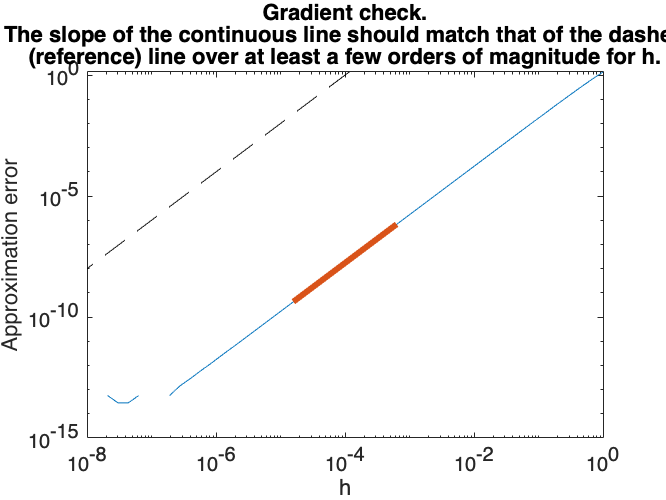

print("graphics/q16_checkgradient", '-depsc')

fprintf("\nCheck Hessian:\n")


Check Hessian:


figure()
checkhessian(prob);

The slope should be 3. It appears to be: 3.00027.
If it is far from 3, then directional derivatives,
the gradient or the Hessian might be erroneous.
Tangency residual should be zero, or very close; residual: 0.
If it is far from 0, then the Hessian is not in the tangent space.
||a*H[d1] + b*H[d2] - H[a*d1+b*d2]|| should be zero, or very close.
	Value: 7.61535e-15 (norm of H[a*d1+b*d2]: 26.5732)
If it is far from 0, then the Hessian is not linear.
<d1, H[d2]> - <H[d1], d2> should be zero, or very close.
	Value: -2.00099 - -2.00099 = 4.44089e-16.
If it is far from 0, then the Hessian is not symmetric.


=== Special message ===
For this manifold, tangent vectors are represented
differently from their ambient space representation.
In practice, this means that when defining
v = problem.ehess(x, u), one may need to call
u = problem.M.tangent2ambient(x, u) first, so as to
transform u into an ambient vector, if this is more
convenient. The output of ehess should be an ambient
vector (it will b

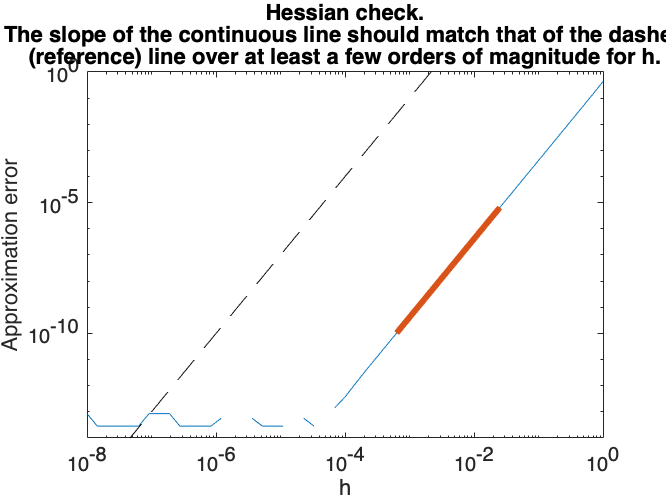

print('graphics/q16_checkhessian', '-depsc')

## Question 22

fprintf("\n––– Question 22 –––\n")


––– Question 22 –––



X0 = prob.init();
cost0 = prob.cost(X0);
repeat=100;
cost_random = zeros(repeat,1);
for i=1:repeat
    cost_random(i) = prob.cost(prob.M.rand());
end
[sigma, mu] = std(cost_random);
fprintf("Initial cost : %f\n", cost0)

Initial cost : -613.499144


fprintf("Random cost  : %f +- %f\n", mu, sigma)

Random cost  : -178.860899 +- 33.167655


## Question 23

fprintf("\n––– Question 23 –––\n")


––– Question 23 –––



X0 = initialization(prob);
mse0 = prob.MSE(X0);
repeat=100;
mse_random = zeros(repeat,1);
for i=1:repeat
    mse_random(i) = prob.MSE(prob.M.rand());
end
[sigma, mu] = std(mse_random);
fprintf("Initial MSE         : %f\n", mse0)

Initial MSE         : 0.269445


fprintf("Random MSE          : %f +- %f\n", mu, sigma)

Random MSE          : 10.987357 +- 1.738104


fprintf("Expected random MSE : 10.5797 (= 2/3 * pi^2 + 4)  \n")

Expected random MSE : 10.5797 (= 2/3 * pi^2 + 4)  


## Question 24

fprintf("\n––– Question 24 –––\n")


––– Question 24 –––


% a) Generate a synthetic problem
clear
q=1; d=3; m=5; ma=1; kappa1=10; kappa2=10; G="complete";
prob = build_problem(d, m, ma, kappa1, kappa2, q, G);
prob.R(:,:,1) = eye(d);

% b) Choose a random initial starting point
X0 = prob.M.rand();

% c) Run RGD (with backtracking) and RTR
option = prob.option;
option.debug = 0;
option.verbosity =2;

disp("– Random initialization")

– Random initialization


disp("RGD:")

RGD:


[~, ~, info_rgd, ~] = steepestdescent(prob, X0, option);

 iter	               cost val	    grad. norm
    0	-8.4920229208292170e+01	3.46351803e+01
    1	-1.1890825996919898e+02	3.72129759e+01
    2	-2.0732059166344496e+02	5.98468359e+01
    3	-3.2596193966806641e+02	3.10502553e+01
    4	-3.2967879719084539e+02	3.83768229e+01
    5	-3.4137133122304658e+02	2.24524226e+01
    6	-3.4329790281117516e+02	2.33767394e+01
    7	-3.4852016670710037e+02	8.89280535e+00
    8	-3.4952928858068151e+02	5.51282206e+00
    9	-3.4994826264820301e+02	3.58822303e+00
   10	-3.5013337152651542e+02	2.33633215e+00
   11	-3.5021530423459944e+02	1.63458904e+00
   12	-3.5025404239760275e+02	1.02469642e+00
   13	-3.5027124665327051e+02	8.00022639e-01
   14	-3.5027144945486543e+02	1.17045074e+00
   15	-3.5027224861423872e+02	1.13570086e+00
   16	-3.5027524688729125e+02	9.95030770e-01
   17	-3.5028363299171849e+02	4.11901227e-01
   18	-3.5028564433161523e+02	1.80391433e-01
   19	-3.5028623728978044e+02	2.31006097e-01
   20	-3.5028677694614100e+02	5.92197909e-02
   21	-3.5

disp("RTR:")

RTR:


[~, ~, info_rtr, ~] = trustregions(prob, X0, option);

           iter                  cost val     grad. norm    numinner     hessvec   numstored   stopreason
              0   -8.4920229208292170e+01   3.463518e+01
acc TR+       1   -1.1474996989884797e+02   3.716505e+01           1           1           1   negative curvature
acc TR+       2   -1.7176800183150183e+02   4.680043e+01           1           1           1   negative curvature
acc           3   -2.9605850960951761e+02   5.114730e+01           1           1           1   negative curvature
acc           4   -3.4705299460558865e+02   1.558892e+01           2           2           2   exceeded trust region
acc           5   -3.5028658286035625e+02   1.662311e-01           3           3           2   reached target residual-kappa (linear)
acc           6   -3.5028690795510408e+02   5.837019e-04           3           3           2   reached target residual-kappa (linear)
acc           7   -3.5028690795973830e+02   3.367896e-07           5           5           3   reached target 

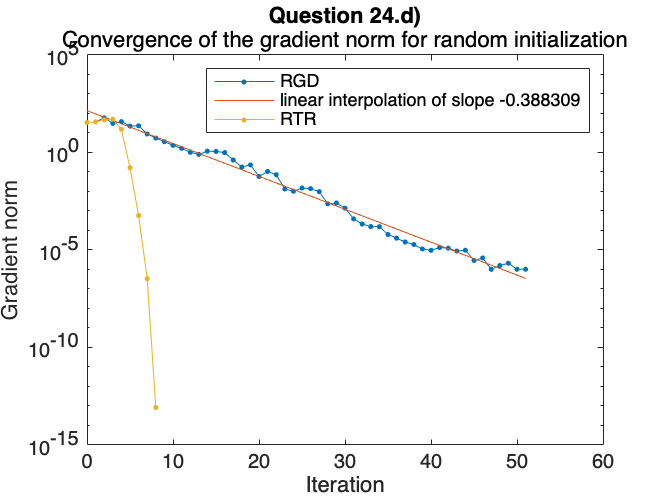


% d) Plot the norm of the gradient
figure()
semilogy([info_rgd.iter], [info_rgd.gradnorm],'.-');
p = polyfit([info_rgd.iter], log([info_rgd.gradnorm]),1);
line = exp(polyval(p,[info_rgd.iter]));
hold on;
semilogy([info_rgd.iter], line);
semilogy([info_rtr.iter], [info_rtr.gradnorm],'.-');
title("Question 24.d)", "Convergence of the gradient norm for random initialization")
legend("RGD",sprintf("linear interpolation of slope %f",p(1)),"RTR")
xlabel("Iteration")
ylabel("Gradient norm")
hold off
print('graphics/q24d', '-depsc')

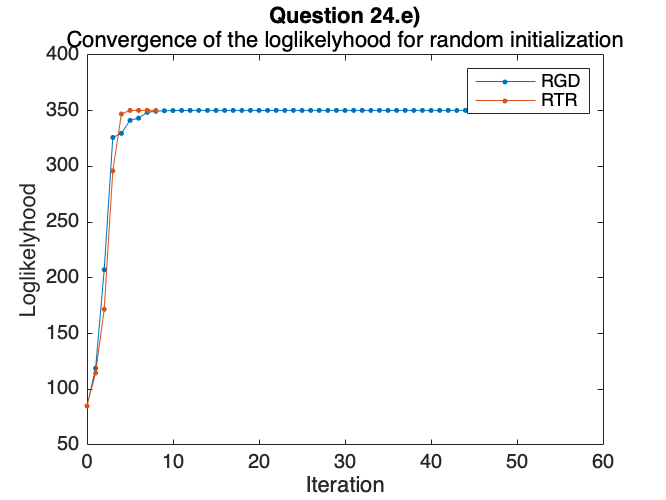


% e) Plot the function value
figure()
plot([info_rgd.iter], -[info_rgd.cost],'.-');
hold on;
plot([info_rtr.iter], -[info_rtr.cost],'.-');
title("Question 24.e)", "Convergence of the loglikelyhood for random initialization")
legend("RGD","RTR")
xlabel("Iteration")
ylabel("Loglikelyhood")
hold off
print('graphics/q24e', '-depsc')

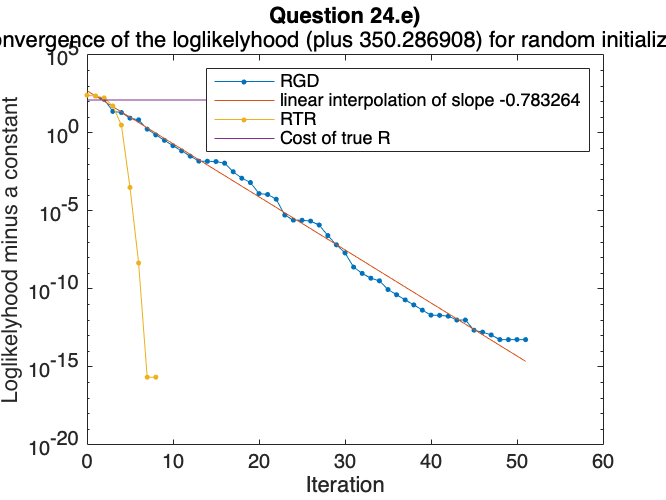


% e) Plot the function value + min reached

step = min([min([info_rgd.cost]), min([info_rtr.cost])]) - eps();
figure()
semilogy([info_rgd.iter], [info_rgd.cost]-step +eps(),'.-');
p = polyfit([info_rgd.iter], log([info_rgd.cost]-step+eps()),1);
line = exp(polyval(p,[info_rgd.iter]));
hold on;
semilogy([info_rgd.iter], line);
semilogy([info_rtr.iter], [info_rtr.cost]-step+eps(),'.-');
semilogy([info_rgd.iter],0*[info_rgd.iter]+ cost(prob,prob.R)-step)
title("Question 24.e)", sprintf("Convergence of the loglikelyhood (plus %f) for random initialization",-step))
legend("RGD",sprintf("linear interpolation of slope %f",p(1)),"RTR","Cost of true R")
xlabel("Iteration")
ylabel("Loglikelyhood minus a constant")
hold off
print('graphics/q24e_step', '-depsc')

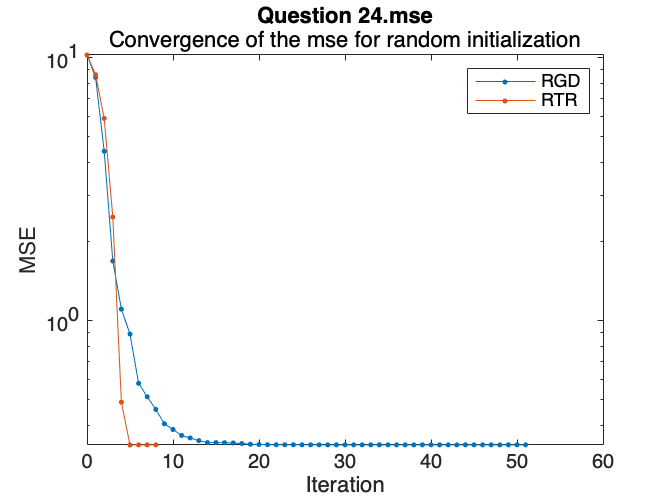


% Plot the MSE
figure()
semilogy([info_rgd.iter], [info_rgd.mse],'.-');
hold on;
semilogy([info_rtr.iter], [info_rtr.mse],'.-');
title("Question 24.mse", "Convergence of the mse for random initialization")
legend("RGD","RTR")
xlabel("Iteration")
ylabel("MSE")
hold off
print('graphics/q24mse', '-depsc')

## f) Use the spectral initialization

X0 = prob.init();

% g) Run RGD and RTR
option = prob.option;
option.debug = 0;
option.verbosity =2;

disp("– Spectral initialization")

– Spectral initialization


disp("RGD:")

RGD:


[~, ~, info_rgd, ~] = steepestdescent(prob, X0, option);

 iter	               cost val	    grad. norm
    0	-3.5028638864625748e+02	1.88264971e-01
    1	-3.5028647828801968e+02	1.91816502e-01
    2	-3.5028675257013015e+02	1.02696655e-01
    3	-3.5028686532868812e+02	3.83334143e-02
    4	-3.5028688696932295e+02	3.10896445e-02
    5	-3.5028689233920534e+02	3.45308890e-02
    6	-3.5028690464928047e+02	8.39300162e-03
    7	-3.5028690676062871e+02	1.05713652e-02
    8	-3.5028690705161466e+02	9.36399032e-03
    9	-3.5028690783103940e+02	3.21582162e-03
   10	-3.5028690787057332e+02	2.80895197e-03
   11	-3.5028690795122043e+02	4.06285799e-04
   12	-3.5028690795824269e+02	3.59539435e-04
   13	-3.5028690795949251e+02	1.24714941e-04
   14	-3.5028690795955976e+02	1.20361375e-04
   15	-3.5028690795970857e+02	2.51170607e-05
   16	-3.5028690795971880e+02	4.25477804e-05
   17	-3.5028690795973796e+02	4.30751720e-06
   18	-3.5028690795973819e+02	2.77599259e-06
   19	-3.5028690795973824e+02	1.58403500e-06
   20	-3.5028690795973824e+02	1.67617210e-06
   21	-3.5

disp("RTR:")

RTR:


[~, ~, info_rtr, ~] = trustregions(prob, X0, option);

           iter                  cost val     grad. norm    numinner     hessvec   numstored   stopreason
              0   -3.5028638864625748e+02   1.882650e-01
acc           1   -3.5028690794850877e+02   9.784470e-04           3           3           2   reached target residual-kappa (linear)
acc           2   -3.5028690795973830e+02   5.972383e-07           4           4           2   reached target residual-theta (superlinear)
Between line above and below, cost function increased by 5.7e-14 (step size: 6.1e-08)
acc           3   -3.5028690795973824e+02   8.784804e-15           9           9           3   reached target residual-theta (superlinear)
Gradient norm tolerance reached; options.tolgradnorm = 1e-07.
Total time is 0.270727 [s] (excludes statsfun)


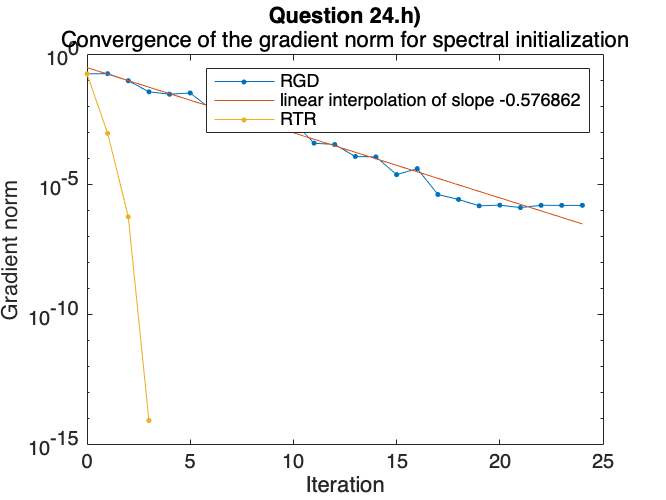


% h) Plot the norm of the gradient and function value

% Gradient
figure()
semilogy([info_rgd.iter], [info_rgd.gradnorm],'.-');
p = polyfit([info_rgd.iter], log([info_rgd.gradnorm]),1);
line = exp(polyval(p,[info_rgd.iter]));
hold on;
semilogy([info_rgd.iter], line);
semilogy([info_rtr.iter], [info_rtr.gradnorm],'.-');
title("Question 24.h)", "Convergence of the gradient norm for spectral initialization")
legend("RGD",sprintf("linear interpolation of slope %f",p(1)),"RTR")
xlabel("Iteration")
ylabel("Gradient norm")
hold off
print('graphics/q24h_grad', '-depsc')

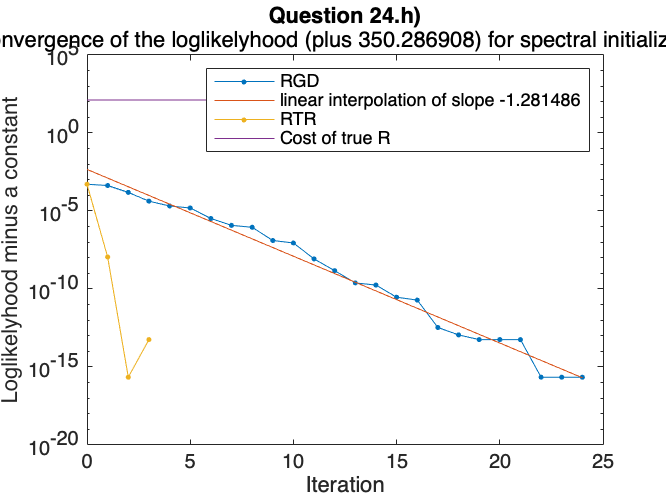


% Function
step = min([min([info_rgd.cost]), min([info_rtr.cost])]) - eps();
figure()
semilogy([info_rgd.iter], [info_rgd.cost]-step+eps(),'.-');
p = polyfit([info_rgd.iter], log([info_rgd.cost]-step+eps()),1);
line = exp(polyval(p,[info_rgd.iter]));
hold on;
semilogy([info_rgd.iter], line);
semilogy([info_rtr.iter], [info_rtr.cost]-step+eps(),'.-');
semilogy([info_rgd.iter],0*[info_rgd.iter]+ cost(prob,prob.R)-step+eps())
title("Question 24.h)", sprintf("Convergence of the loglikelyhood (plus %f) for spectral initialization",-step))
legend("RGD",sprintf("linear interpolation of slope %f",p(1)),"RTR","Cost of true R")
xlabel("Iteration")
ylabel("Loglikelyhood minus a constant")
hold off
print('graphics/q24h_fun', '-depsc')

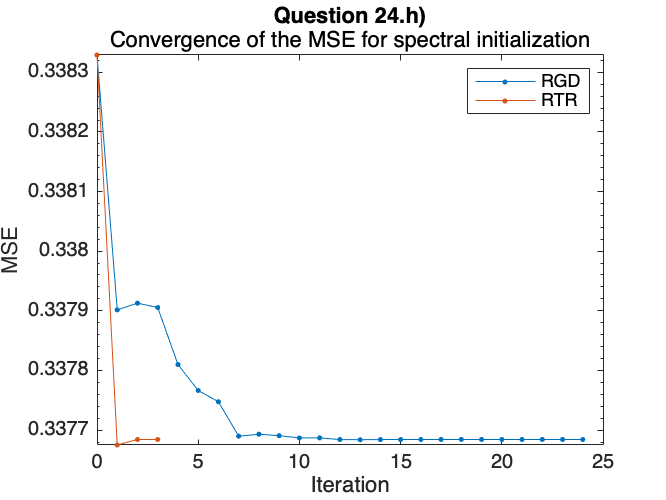


% MSE
figure()
semilogy([info_rgd.iter], [info_rgd.mse],'.-');
hold on;
semilogy([info_rtr.iter], [info_rtr.mse],'.-');
title("Question 24.h)", "Convergence of the MSE for spectral initialization")
legend("RGD","RTR")
xlabel("Iteration")
ylabel("MSE")
hold off
print('graphics/q24h_mse', '-depsc')

## Question 25

fprintf("\n––– Question 25 –––\n")


––– Question 25 –––


% a) Generate a synthetic problem
clear
q=0.7; d=3; m=40; ma=5; kappa1=5; kappa2=0; G="complete";
prob = build_problem(d, m, ma, kappa1, kappa2, q, G);


% b) Choose a random initial starting point
X0 = prob.M.rand();

% c) Run RGD (with backtracking) and RTR
option = prob.option;
option.debug = 0;
option.verbosity =2;
disp("– Random initialization")

– Random initialization


disp("RGD:")

RGD:


[~, ~, info_rgd, ~] = steepestdescent(prob, X0, option);

 iter	               cost val	    grad. norm
    0	-3.7398271280480676e+03	2.09791450e+02
    1	-3.9539106630226988e+03	2.22391339e+02
    2	-4.7518254774595607e+03	2.50344081e+02
    3	-6.4292086195496504e+03	2.81201287e+02
    4	-7.5165452974892560e+03	4.58735524e+02
    5	-9.1379955504247118e+03	3.36129778e+02
    6	-9.1778855328478039e+03	4.27051603e+02
    7	-9.3311835446637087e+03	3.94392382e+02
    8	-9.8234091830099405e+03	2.61501030e+02
    9	-1.0212717052843524e+04	2.62860583e+02
   10	-1.0284683478181236e+04	3.16423464e+02
   11	-1.0518012765308409e+04	1.98183200e+02
   12	-1.0609578408103278e+04	1.24430513e+02
   13	-1.0637310000931062e+04	8.80024819e+01
   14	-1.0663433556669836e+04	8.67961790e+00
   15	-1.0663775761770579e+04	6.39974683e+00
   16	-1.0663915875291408e+04	8.41092766e+00
   17	-1.0664170826403160e+04	3.39214112e+00
   18	-1.0664245788664924e+04	5.31365987e+00
   19	-1.0664318223231903e+04	3.81950718e+00
   20	-1.0664364332288162e+04	2.46434168e+00
   21	-1.0

disp("RTR:")

RTR:


[~, ~, info_rtr, ~] = trustregions(prob, X0, option);

           iter                  cost val     grad. norm    numinner     hessvec   numstored   stopreason
              0   -3.7398271280480676e+03   2.097915e+02
acc TR+       1   -4.2739141970600813e+03   2.325074e+02           1           1           1   negative curvature
acc           2   -5.3099938534613420e+03   2.664084e+02           1           1           1   negative curvature
acc           3   -6.4441296709153876e+03   2.632758e+02           1           1           1   negative curvature
acc           4   -7.5191470456492461e+03   2.842954e+02           1           1           1   negative curvature
acc           5   -8.5702196735958696e+03   2.904819e+02           1           1           1   negative curvature
acc           6   -9.6073202956463283e+03   3.262754e+02           1           1           1   negative curvature
acc           7   -1.0386996448760754e+04   2.031628e+02           1           1           1   exceeded trust region
acc           8   -1.064151597022685

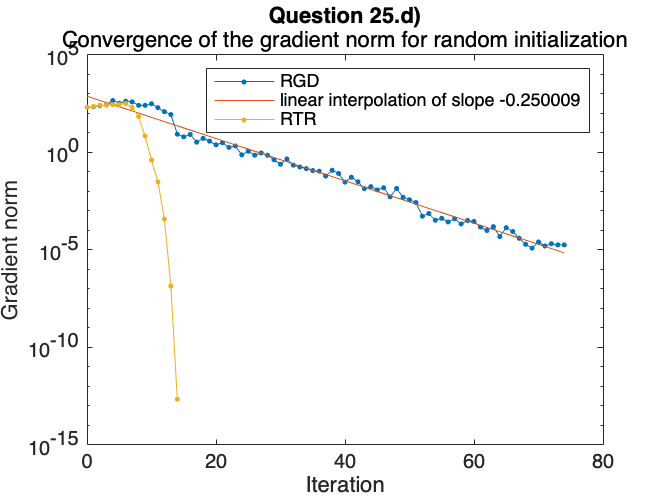


% d) Plot the norm of the gradient
figure()
semilogy([info_rgd.iter], [info_rgd.gradnorm],'.-');
p = polyfit([info_rgd.iter], log([info_rgd.gradnorm]),1);
line = exp(polyval(p,[info_rgd.iter]));
hold on;
semilogy([info_rgd.iter], line);
semilogy([info_rtr.iter], [info_rtr.gradnorm],'.-');
title("Question 25.d)", "Convergence of the gradient norm for random initialization")
legend("RGD",sprintf("linear interpolation of slope %f",p(1)),"RTR")
xlabel("Iteration")
ylabel("Gradient norm")
hold off
print('graphics/q25d', '-depsc')

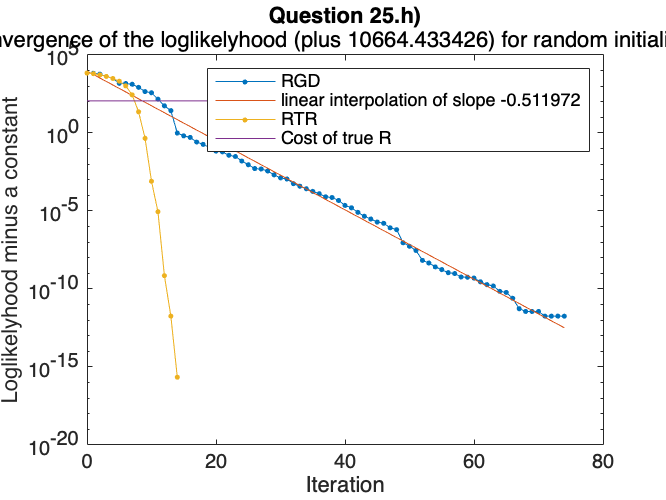


% e) Plot the function value
step = min([min([info_rgd.cost]), min([info_rtr.cost])]) - eps();
figure()
semilogy([info_rgd.iter], [info_rgd.cost]-step+eps(),'.-');
p = polyfit([info_rgd.iter], log([info_rgd.cost]-step+eps()),1);
line = exp(polyval(p,[info_rgd.iter]));
hold on;
semilogy([info_rgd.iter], line);
semilogy([info_rtr.iter], [info_rtr.cost]-step+eps(),'.-');
semilogy([info_rgd.iter],0*[info_rgd.iter]+ cost(prob,prob.R)-step+eps())
title("Question 25.h)", sprintf("Convergence of the loglikelyhood (plus %f) for random initialization",-step))
legend("RGD",sprintf("linear interpolation of slope %f",p(1)),"RTR","Cost of true R")
xlabel("Iteration")
ylabel("Loglikelyhood minus a constant")
hold off
print('graphics/q25e', '-depsc')

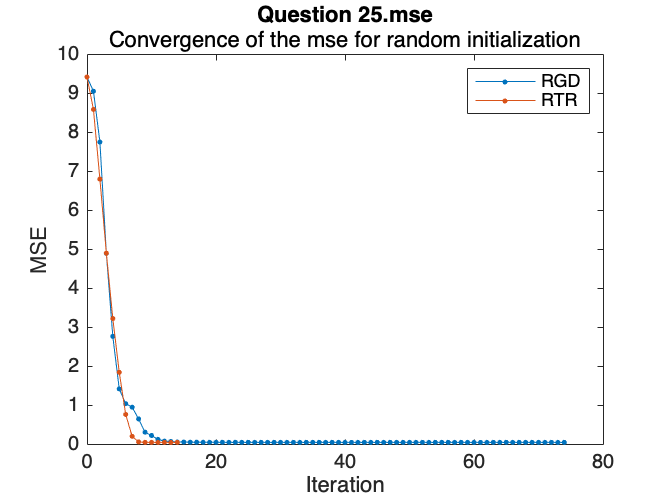


% Plot the MSE
figure()
plot([info_rgd.iter], [info_rgd.mse],'.-');
hold on;
plot([info_rtr.iter], [info_rtr.mse],'.-');
title("Question 25.mse", "Convergence of the mse for random initialization")
legend("RGD","RTR")
xlabel("Iteration")
ylabel("MSE")
hold off
print('graphics/q25mse', '-depsc')

## f) Use the spectral initialization

X0 = prob.init();

% g) Run RGD and RTR
option = prob.option;
option.debug = 0;
option.verbosity =2;
disp("– Spectral initialization")

– Spectral initialization


disp("RGD:")

RGD:


[~, ~, info_rgd, ~] = steepestdescent(prob, X0, option);

 iter	               cost val	    grad. norm
    0	-1.0661731601652784e+04	2.37580163e+01
    1	-1.0664069579250689e+04	8.31128548e+00
    2	-1.0664325718339405e+04	2.69336100e+00
    3	-1.0664345335592683e+04	3.73405184e+00
    4	-1.0664392170351413e+04	1.19553838e+00
    5	-1.0664414543394791e+04	1.71872228e+00
    6	-1.0664425309472463e+04	5.68508310e-01
    7	-1.0664426948984847e+04	1.23354546e+00
    8	-1.0664431321853708e+04	4.40078130e-01
    9	-1.0664432030119904e+04	3.51937961e-01
   10	-1.0664432470018954e+04	2.95006933e-01
   11	-1.0664432804086850e+04	2.06688432e-01
   12	-1.0664432921514057e+04	2.68565035e-01
   13	-1.0664433171743618e+04	8.98414393e-02
   14	-1.0664433351711381e+04	1.56014948e-01
   15	-1.0664433422354658e+04	3.39451598e-02
   16	-1.0664433425679428e+04	9.44966420e-03
   17	-1.0664433425947602e+04	5.52217075e-03
   18	-1.0664433426070120e+04	3.27503386e-03
   19	-1.0664433426099366e+04	6.04160280e-03
   20	-1.0664433426187519e+04	3.15428466e-03
   21	-1.0

disp("RTR:")

RTR:


[~, ~, info_rtr, ~] = trustregions(prob, X0, option);

           iter                  cost val     grad. norm    numinner     hessvec   numstored   stopreason
              0   -1.0661731601652784e+04   2.375802e+01
acc           1   -1.0664333462061655e+04   2.355942e+00           2           2           2   reached target residual-kappa (linear)
acc           2   -1.0664433369687322e+04   1.097383e-01           4           4           3   reached target residual-kappa (linear)
acc           3   -1.0664433425505234e+04   8.202619e-03           2           2           2   reached target residual-kappa (linear)
acc           4   -1.0664433426288826e+04   1.683914e-05           6           6           3   reached target residual-theta (superlinear)
acc           5   -1.0664433426288830e+04   1.194496e-10          12          12           2   reached target residual-theta (superlinear)
Gradient norm tolerance reached; options.tolgradnorm = 1.28205e-09.
Total time is 34.016645 [s] (excludes statsfun)


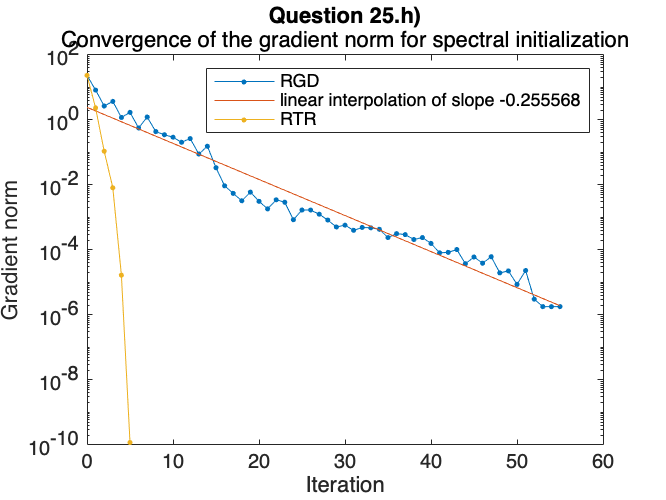


% h) Plot the norm of the gradient and function value

% Gradient
figure()
semilogy([info_rgd.iter], [info_rgd.gradnorm],'.-');
p = polyfit([info_rgd.iter], log([info_rgd.gradnorm]),1);
line = exp(polyval(p,[info_rgd.iter]));
hold on;
semilogy([info_rgd.iter], line);
semilogy([info_rtr.iter], [info_rtr.gradnorm],'.-');
title("Question 25.h)", "Convergence of the gradient norm for spectral initialization")
legend("RGD",sprintf("linear interpolation of slope %f",p(1)),"RTR")
xlabel("Iteration")
ylabel("Gradient norm")
hold off
print('graphics/q25h_grad', '-depsc')

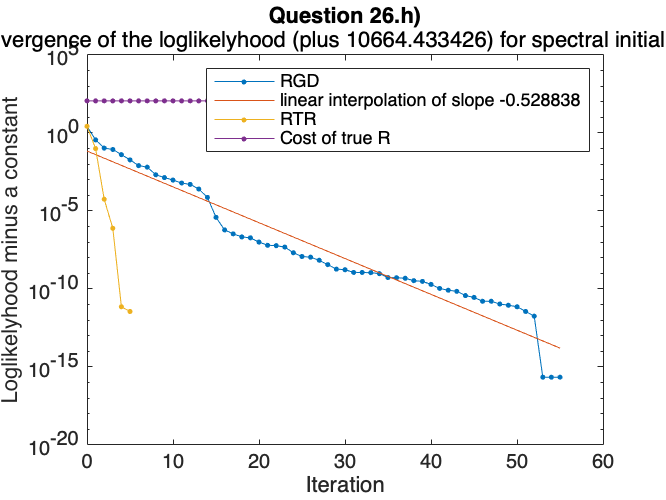


% Function
step = min([min([info_rgd.cost]), min([info_rtr.cost])]) - eps();
figure()
semilogy([info_rgd.iter], [info_rgd.cost]-step+eps(),'.-');
p = polyfit([info_rgd.iter], log([info_rgd.cost]-step+eps()),1);
line = exp(polyval(p,[info_rgd.iter]));
hold on;
semilogy([info_rgd.iter], line);
semilogy([info_rtr.iter], [info_rtr.cost]-step+eps(),'.-');
semilogy([info_rgd.iter],0*[info_rgd.iter]+ cost(prob,prob.R)-step+eps(),'.-')
title("Question 26.h)", sprintf("Convergence of the loglikelyhood (plus %f) for spectral initialization",-step))
legend("RGD",sprintf("linear interpolation of slope %f",p(1)),"RTR","Cost of true R")
xlabel("Iteration")
ylabel("Loglikelyhood minus a constant")
hold off
print('graphics/q25h_fun', '-depsc')

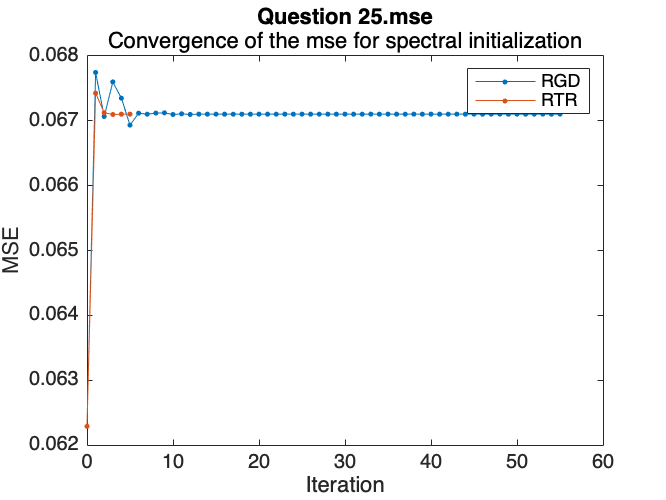


% MSE
figure()
plot([info_rgd.iter], [info_rgd.mse],'.-');
hold on;
plot([info_rtr.iter], [info_rtr.mse],'.-');
title("Question 25.mse", "Convergence of the mse for spectral initialization")
legend("RGD","RTR")
xlabel("Iteration")
ylabel("MSE")
hold off
print('graphics/q25h_mse', '-depsc')

## Question 26

fprintf("\n––– Question 26 –––\n")


––– Question 26 –––


% a) Generate a synthetic problem
clear
q=0.7; d=3; m=40; ma=5; kappa1=5; kappa2=0; G="E-R";
prob = build_problem(d, m, ma, kappa1, kappa2, q, G);

% f) Use the spectral initialization
X0 = prob.init();

% g) Run RGD and RTR
option = prob.option;
option.debug = 0;
option.verbosity =2;

[~, ~, info_rtr, ~] = trustregions(prob, X0, option);

           iter                  cost val     grad. norm    numinner     hessvec   numstored   stopreason
              0   -8.2999608429185573e+03   1.877275e+01
acc           1   -8.3021638149074188e+03   1.594723e+00           4           4           2   reached target residual-kappa (linear)
acc           2   -8.3021864095025539e+03   4.638027e-02           5           5           3   reached target residual-kappa (linear)
acc           3   -8.3021864233978558e+03   1.551893e-03           5           5           3   reached target residual-theta (superlinear)
acc           4   -8.3021864234140667e+03   8.711611e-07           8           8           2   reached target residual-theta (superlinear)
acc           5   -8.3021864234140667e+03   4.069927e-13          17          17           3   reached target residual-theta (superlinear)
Gradient norm tolerance reached; options.tolgradnorm = 1.72712e-09.
Total time is 39.986032 [s] (excludes statsfun)


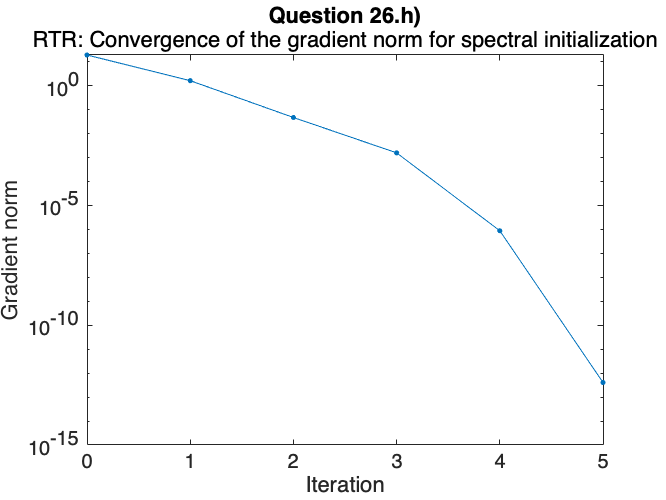


% h) Plot the norm of the gradient and function value

% Gradient
figure()
semilogy([info_rtr.iter], [info_rtr.gradnorm],'.-');
title("Question 26.h)", "RTR: Convergence of the gradient norm for spectral initialization")
xlabel("Iteration")
ylabel("Gradient norm")
print('graphics/q26h_grad', '-depsc')

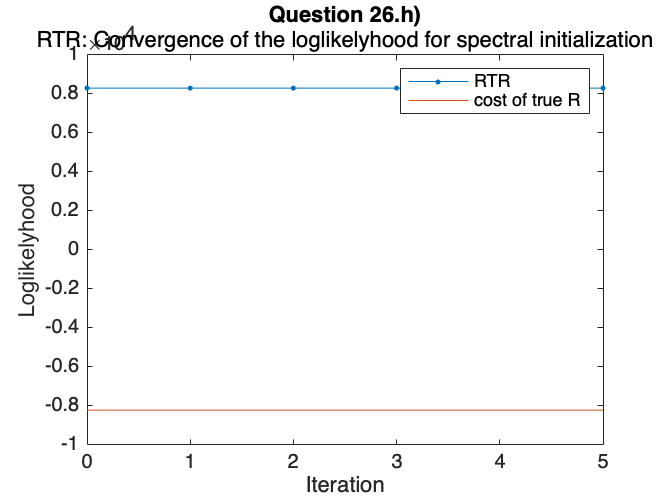


% Function
figure()
plot([info_rtr.iter], -[info_rtr.cost],'.-');
hold on;
plot([info_rtr.iter],0*[info_rtr.iter]+ cost(prob,prob.R))
legend("RTR","cost of true R")
title("Question 26.h)", "RTR: Convergence of the loglikelyhood for spectral initialization")
xlabel("Iteration")
ylabel("Loglikelyhood")
print('graphics/q26h_fun', '-depsc')

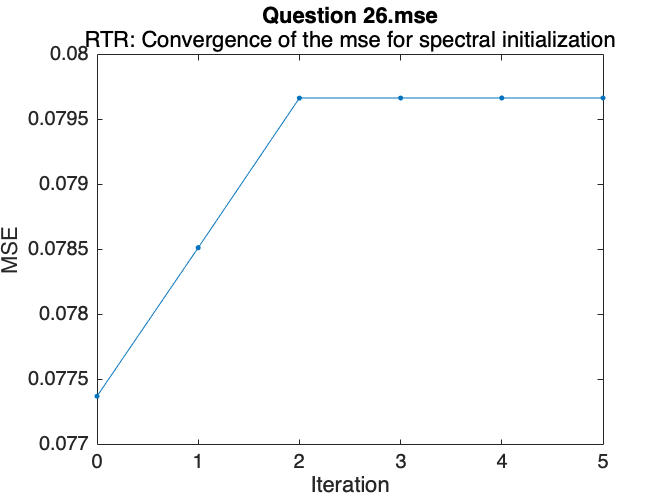


% MSE
figure()
plot([info_rtr.iter], [info_rtr.mse],'.-');
title("Question 26.mse", "RTR: Convergence of the mse for spectral initialization")
xlabel("Iteration")
ylabel("MSE")
hold off
print('graphics/q26h_mse', '-depsc')

## Question 27

fprintf("\n––– Question 27 –––\n")


––– Question 27 –––


% Generate a synthetic problem
clear
d=3; m=10; ma=1; kappa1=100; kappa2=0; G="complete";
a=0; b=1; n=3;
qq = a+(b-a)*(logspace(0,1,5)-1)/9;
repeat = 5;
for i=1:length(qq)
    fprintf("%i/%i\n",i,length(qq))
    prob = build_problem(d, m, ma, kappa1, kappa2, qq(i), G);
    option = prob.option;
    option.verbosity = 0;
    option.tolgradnorm = 1e-3;
    for j=1:repeat
        fprintf("               %i/%i\n",j,repeat)
        X0 = prob.M.rand();
        dum(i,j) = prob.MSE(X0);
        [X, ~, info, ~] = trustregions(prob, prob.M.rand(), option);
        if info(end).gradnorm > option.tolgradnorm
            warn("RTR did not reach Gradient norm tolerance")
        end
        rand(i,j) = prob.MSE(X);
    end
    [X, ~, info, ~] = trustregions(prob, prob.init(), option);
    if info(end).gradnorm > option.tolgradnorm
        warn("RTR did not reach Gradient norm tolerance")
    end
    init(i,1) = prob.MSE(X);
end

1/5


               1/5
               2/5
               3/5
               4/5
               5/5


2/5


               1/5
               2/5
               3/5
               4/5
               5/5


3/5


               1/5
               2/5
               3/5
               4/5
               5/5


4/5


               1/5
               2/5
               3/5
               4/5
               5/5


5/5


               1/5
               2/5
               3/5
               4/5
               5/5


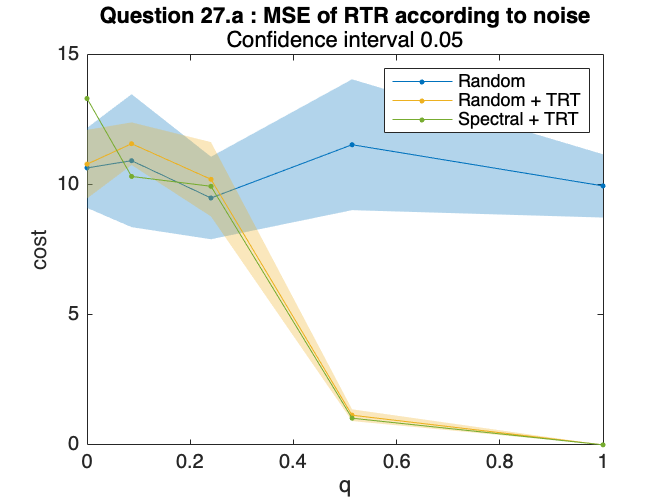

%diff = (rand-init);
alpha=0.05;
[sigma.dum,mu.dum] = std(dum,0,2);
[sigma.rand,mu.rand] = std(rand,0,2);
%[sigma.init,mu.init] = std(init,0,2);
%[sigma.diff,mu.diff] = std(diff,0,2);

figure()

p = plot(qq,mu.dum,'.-'); hold on;
col= p.Color;
interval1 = mu.dum + sigma.dum * norminv(1-alpha/2)/sqrt(repeat) ;
interval2 = mu.dum - sigma.dum * norminv(1-alpha/2)/sqrt(repeat) ;
qq1 = [qq, fliplr(qq)];
inBetween = [interval1', fliplr(interval2')];
fill(qq1, inBetween, col,'FaceAlpha',0.3,"EdgeColor","none");

p = plot(qq,mu.rand,'.-'); hold on;
col= p.Color;
interval1 = mu.rand + sigma.rand * norminv(1-alpha/2)/sqrt(repeat) ;
interval2 = mu.rand - sigma.rand * norminv(1-alpha/2)/sqrt(repeat) ;
qq1 = [qq, fliplr(qq)];
inBetween = [interval1', fliplr(interval2')];
fill(qq1, inBetween, col,'FaceAlpha',0.3,"EdgeColor","none");

p=plot(qq,init,'.-');
% col= p.Color;
% interval1 = mu.init + sigma.init * norminv(1-alpha/2)/sqrt(repeat) ;
% interval2 = mu.init - sigma.init * norminv(1-alpha/2)/sqrt(repeat)  ;
% inBetween = [interval1', fliplr(interval2')];
% fill(qq1, inBetween, col,'FaceAlpha',0.1,"EdgeColor","none");


% p = plot(qq,mu.diff,'.-');
% hold on
% col = p.Color;
% qq1 = [qq, fliplr(qq)];
% interval1 = mu.diff + sigma.diff * norminv(1-alpha/2)/sqrt(repeat) ;
% interval2 = mu.diff - sigma.diff * norminv(1-alpha/2)/sqrt(repeat)  ;
% inBetween = [interval1', fliplr(interval2')];
% fill(qq1, inBetween, col,'FaceAlpha',0.1,"EdgeColor","none");

legend("Random","","Random + TRT","","Spectral + TRT")
title("Question 27.a : MSE of RTR according to noise",sprintf("Confidence interval %g",alpha))
xlabel("q")
ylabel("cost")
print('graphics/q27a', '-depsc')

## Question 28

fprintf("\n––– Question 28 –––\n")


––– Question 28 –––
